# Signal and noise analysis by bins

Here we want to see the differences between different spatial bins on the track when it comes to the encoded spatial signal and its associated noise. This analysis extends the previous signal and noise analysis which looked at the median quantities across spatial bins. We group the bins into 5 categories: edge, far side, mid side, near side, and central (E, FS, MS, NS, C).

Each includes the following bins: E (1,2, 18,19), FS (3,4, 16,17), MS (5,6 14,15), NS (7,8, 12,13), C (9,10,11)

Load the adjacent metrics database using events:

t_ = tic;
load('adjacent_metrics_events_transients_agg_210707-152508_0.mat', 'res');
toc(t_)

Elapsed time is 115.073389 seconds.


Organizing the signal, noise, and shuffled noise:

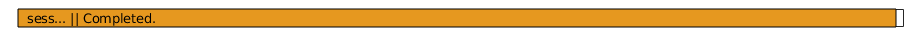

n_sess = numel(res);

[signal, noise, noise_shuf] = deal(cell(1,n_sess));

n_bin_bounds = 38;

progressbar('sess...');
for sess_i = 1:n_sess
    R = res(sess_i).results_table;
    [n_reps, n_n] = size(R);
    [signal{sess_i}, noise{sess_i}, noise_shuf{sess_i}] = deal(zeros(n_reps, n_n, n_bin_bounds));
    for rep_i = 1:n_reps
        for n_i = 1:n_n
            T = R{rep_i, n_i};
            signal{sess_i}(rep_i, n_i, :) = T{'m', 'se'};
            noise{sess_i}(rep_i, n_i, :) = T{'m', 'ce'};
            noise_shuf{sess_i}(rep_i, n_i, :) = T{'m', 'ue'};
        end
    end
    progressbar(sess_i/n_sess);
end

using_mice = {'Mouse2022', 'Mouse2024', 'Mouse2028'};
ix_special = SessManager.special_sessions_usable_index(using_mice);

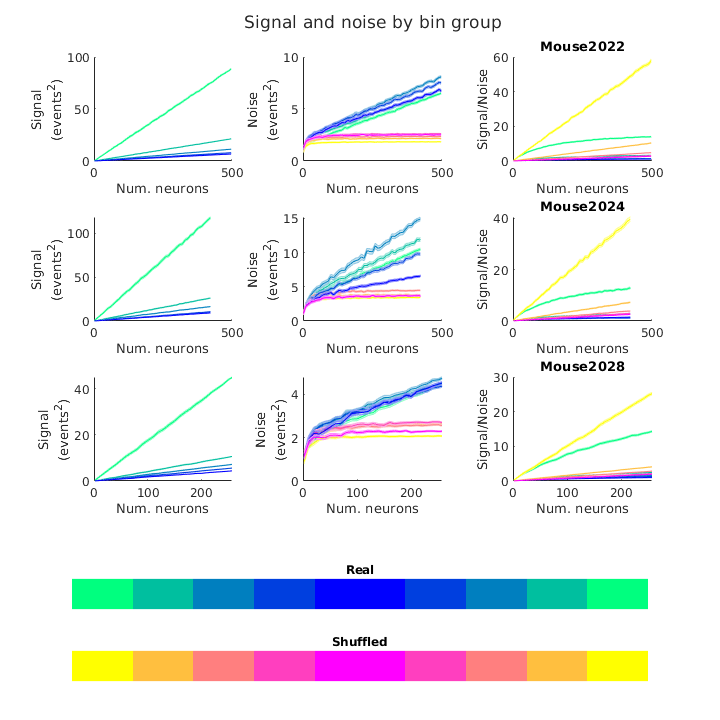

c_colors = flipud(winter(5));
c_colors_shuf = flipud(spring(5));

figure('Units', 'inches', 'Position',[0 0 7.5 7.5]);
t = tiledlayout(4,3, 'TileSpacing', 'tight');
for i = 1:numel(ix_special)
    new_plot_sess(false, ix_special(i), signal, noise, noise_shuf, res);
    title(using_mice{i});            
end
c_legend(c_colors, [0.1 0.15 0.8 0.05], 'Real');
c_legend(c_colors_shuf, [0.1 0.05 0.8 0.05], 'Shuffled');
title(t, 'Signal and noise by bin group');
Utils.printto('events_figs/f3_supplements', 'snr_by_bin.pdf');

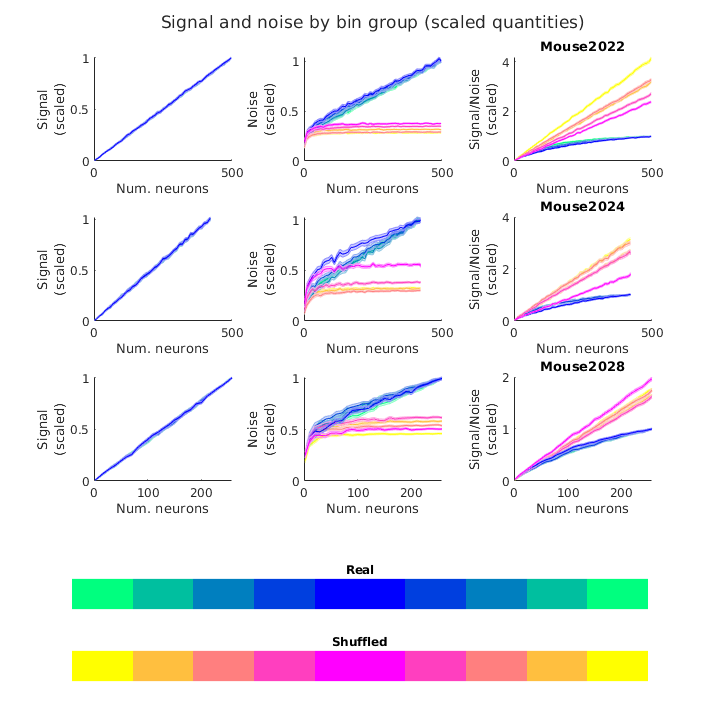

figure('Units', 'inches', 'Position',[0 0 7.5 7.5]);
t = tiledlayout(4,3, 'TileSpacing', 'tight');
for i = 1:numel(ix_special)
    new_plot_sess(true, ix_special(i), signal, noise, noise_shuf, res);
    title(using_mice{i});            
end
c_legend(c_colors, [0.1 0.15 0.8 0.05], 'Real');
c_legend(c_colors_shuf, [0.1 0.05 0.8 0.05], 'Shuffled');
title(t, 'Signal and noise by bin group (scaled quantities)');
Utils.printto('events_figs/f3_supplements', 'snr_by_bin_scaled.pdf');

Showing the asymptotic SNR, real and shuffled, and the asymptotic SNR ratio for all sessions, as well as grouped by mouse:

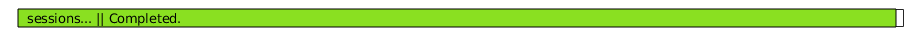

[asnr, asnr_conf,...
        asnr_shuf, asnr_shuf_conf,...
        asnr_ratio, asnr_ratio_conf] = deal(zeros(numel(res), 5));

progressbar('sessions...');
for ix = 1:numel(res)
    [asnr(ix,:), asnr_conf(ix,:),...
        asnr_shuf(ix,:), asnr_shuf_conf(ix,:),...
        asnr_ratio(ix,:), asnr_ratio_conf(ix,:)] =...
    calculate_asymp_snr(ix, signal, noise, noise_shuf, res);
    progressbar(ix/numel(res));
end


[~, sess_mice] = SessManager.usable_sess_id_list;

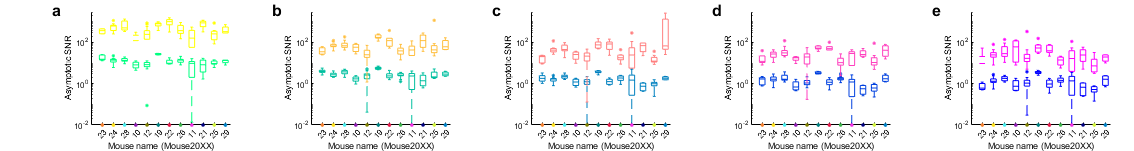

p = Pub(30,4,'rows',1,'columns',5,'hspacing',0.07);
set(p.h, 'Renderer', 'painters');

logscale = true;

c_colors = flipud(winter(5));
c_colors_shuf = flipud(spring(5));

for c_i = 1:5
    p.panel(c_i, 'ylab', 'Asymptotic SNR', 'xlab', 'Mouse name (Mouse20XX)', 'x_shift', -0.04);
    v1 = asnr(:,c_i);
    v1_conf = asnr_conf(:,c_i);

    v2 = asnr_shuf(:,c_i);
    v2_conf = asnr_shuf_conf(:,c_i);

    mice = sess_mice;

    hold on;
    bf_ = @(x, c) boxplot(x, Utils.cf_(@(x)x(end-1:end), mice), 'Colors', c, 'BoxStyle', 'outline', 'Symbol', '.');
    bf_(v1, c_colors(c_i,:)); bf_(v2, c_colors_shuf(c_i,:));
    xtickangle(45);
    if logscale
        set(gca, 'YScale', 'log');
    end
    x_coords = get(gca, 'XTick');
    mouse_id = get(gca, 'XTickLabel');
    mouse_id = Utils.cf_(@(x)['Mouse20' x], mouse_id);
    mouse_colors = DecodeTensor.mcolor(mouse_id);
    ylim([1e-2 3e3]);
    for i = 1:numel(x_coords)
        x_val = x_coords(i);
        color = mouse_colors{i};
        hold on;
        y_bottom = ylim;
        y_bottom = y_bottom(1);
        scatter(x_val, y_bottom, 8, color, 'filled');
    end
end
p.format;
print -bestfit -dpdf events_figs/f3_supplements/asymp_snr_by_bin.pdf

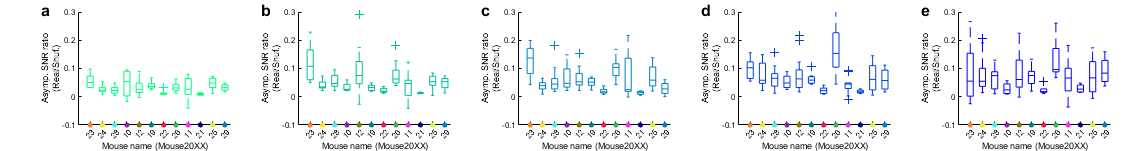

p = Pub(30,4,'rows',1,'columns',5,'hspacing',0.07);
set(p.h, 'Renderer', 'painters');

logscale = false;

c_colors = flipud(winter(5));
c_colors_shuf = flipud(spring(5));

for c_i = 1:5
    p.panel(c_i, 'ylab', sprintf('Asymp. SNR ratio\n(Real/Shuf.)'), 'xlab', 'Mouse name (Mouse20XX)', 'x_shift', -0.05);
    v1 = asnr_ratio(:,c_i);
    v1_conf = asnr_ratio_conf(:,c_i);

    %v2 = asnr_shuf(:,c_i);
    %v2_conf = asnr_shuf_conf(:,c_i);

    mice = sess_mice;

    hold on;
    bf_ = @(x, c) boxplot(x, Utils.cf_(@(x)x(end-1:end), mice), 'Colors', c, 'BoxStyle', 'outline', 'Symbol', '+');
    bf_(v1, c_colors(c_i,:));% bf_(v2, c_colors_shuf(c_i,:));
    xtickangle(45);
    if logscale
        set(gca, 'YScale', 'log');
    end
    x_coords = get(gca, 'XTick');
    mouse_id = get(gca, 'XTickLabel');
    mouse_id = Utils.cf_(@(x)['Mouse20' x], mouse_id);
    mouse_colors = DecodeTensor.mcolor(mouse_id);
    ylim([-0.1 0.3]);
    for i = 1:numel(x_coords)
        x_val = x_coords(i);
        color = mouse_colors{i};
        hold on;
        y_bottom = ylim;
        y_bottom = y_bottom(1);
        scatter(x_val, y_bottom, 8*2, color, 'filled');
    end
end
p.format;
print -bestfit -dpdf events_figs/f3_supplements/asymp_snr_ratio_by_bin.pdf

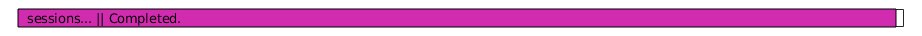

[s_slope, s_slope_conf, n_slope, n_slope_conf, asnr, asnr_conf] = deal(zeros(numel(res), 38));

progressbar('sessions...');
for ix = 1:numel(res)
    [s_slope(ix,:), s_slope_conf(ix,:), n_slope(ix,:), n_slope_conf(ix,:), asnr(ix,:), asnr_conf(ix,:)] =...
        calculate_slopes_bins(ix, signal, noise, noise_shuf, res);
    progressbar(ix/numel(res));
end

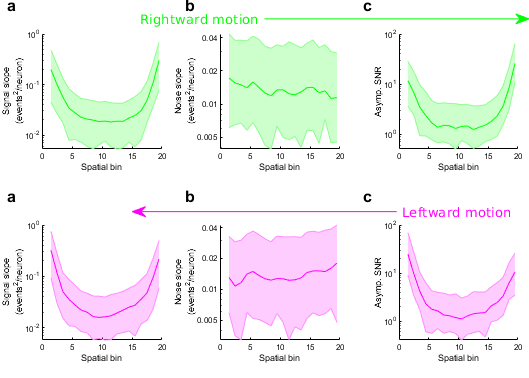

p = Pub(14,10, 'rows', 2, 'columns', 3);

kd = bb2kd((1:38).');
d = kd(:,2);

r_plot = @(a,c) shadedErrorBar(1.5:19.5, median(a), [quantile(a,0.75) ; quantile(a,0.25)], 'lineprops', c);

p.panel(1, 'xlab', 'Spatial bin', 'ylab', sprintf('Signal slope\n(events^2/neuron)'), 'letter', 'a');
r_plot(s_slope(:,d==0), 'g');
set(gca, 'YScale', 'log');

p.panel(4, 'xlab', 'Spatial bin', 'ylab', sprintf('Signal slope\n(events^2/neuron)'), 'letter', 'a');
r_plot(s_slope(:,d==1), 'm');
set(gca, 'YScale', 'log');

p.panel(2, 'xlab', 'Spatial bin', 'ylab', sprintf('Noise slope\n(events^2/neuron)'), 'letter', 'b');
r_plot(n_slope(:,d==0), 'g');
set(gca, 'YScale', 'log');
set(gca, 'YTick', [0.5 1 2 4]/100);

p.panel(5, 'xlab', 'Spatial bin', 'ylab', sprintf('Noise slope\n(events^2/neuron)'), 'letter', 'b');
r_plot(n_slope(:,d==1), 'm');
set(gca, 'YScale', 'log');
set(gca, 'YTick', [0.5 1 2 4]/100);

p.panel(3, 'xlab', 'Spatial bin', 'ylab', 'Asymp. SNR', 'letter', 'c');
r_plot(asnr(:,d==0), 'g');
set(gca, 'YScale', 'log');

p.panel(6, 'xlab', 'Spatial bin', 'ylab', 'Asymp. SNR', 'letter', 'c');
r_plot(asnr(:,d==1), 'm');
set(gca, 'YScale', 'log');

annotation('textarrow', [10 20]/20, [1 1]   - 0.05, 'String', 'Rightward motion', 'Color', 'g', 'HorizontalAlignment',"left");
annotation('textarrow', [15 5]/20, [1 1]/2 - 0.06, 'String', 'Leftward motion', 'Color', 'm', 'HorizontalAlignment',"right");

p.format;
Utils.printto('events_figs/f3_supplements', 'slopes_by_bin.pdf');

ns_right = n_slope(:,d==0);
mean(ns_right(:,1))

ans = 0.0195

mean(ns_right(:,end))

ans = 0.0147

signrank(ns_right(:,1), ns_right(:,end), "tail","right")

ans = 1.9504e-06

ns_left = n_slope(:,d==1);
mean(ns_left(:,end))

ans = 0.0198

mean(ns_left(:,1))

ans = 0.0152

signrank(ns_left(:,end), ns_left(:,1), "tail","right")

ans = 4.0805e-05

fprintf('Noise slope shrinks by %g%% at the end of the run compared to the start (right runs)\np = %g (1-tailed signrank test)',...
    (mean(ns_right(:,1)) - mean(ns_right(:,end))) ./ mean(ns_right(:,1)) * 100,...
    signrank(ns_right(:,1), ns_right(:,end), "tail","right"));

Noise slope shrinks by 24.6371% at the end of the run compared to the start (right runs)
p = 1.95035e-06 (1-tailed signrank test)

fprintf('Noise slope shrinks by %g%% at the end of the run compared to the start (left runs)\np = %g (1-tailed signrank test)',...
    (mean(ns_left(:,end)) - mean(ns_left(:,1))) ./ mean(ns_left(:,end)) * 100,...
    signrank(ns_left(:,end), ns_left(:,1), "tail","right"));

Noise slope shrinks by 23.5539% at the end of the run compared to the start (left runs)
p = 4.08052e-05 (1-tailed signrank test)

dp_right = real(sqrt(asnr(:,d==0)));
dp_left = real(sqrt(asnr(:,d==1)));

dp_table_right = array2table(median(dp_right(:,[1 10 19])), 'VariableNames',{'Bin1 d''', 'Bin10 d''', 'Bin19 d'''})

dp_table_right = 1×3 table
    Bin1 d'    Bin10 d'    Bin19 d'
    _______    ________    ________

    3.4325      1.1966      5.0887 


dp_table_left = array2table(median(dp_left(:,[1 10 19])), 'VariableNames',{'Bin1 d''', 'Bin10 d''', 'Bin19 d'''})

dp_table_left = 1×3 table
    Bin1 d'    Bin10 d'    Bin19 d'
    _______    ________    ________

    4.9823      1.055       3.253  



p_1_vs_10_right = signrank(dp_right(:,1), dp_right(:,10))

p_1_vs_10_right = 2.8431e-18

p_1_vs_10_left = signrank(dp_left(:,1), dp_left(:,10))

p_1_vs_10_left = 2.6066e-19


p_19_vs_10_right = signrank(dp_right(:,19), dp_right(:,10))

p_19_vs_10_right = 3.6068e-19

p_19_vs_10_left = signrank(dp_left(:,19), dp_left(:,10))

p_19_vs_10_left = 1.2055e-18


p_1_vs_19_right = signrank(dp_right(:,1), dp_right(:,19))

p_1_vs_19_right = 1.2592e-16

p_1_vs_19_left = signrank(dp_left(:,1), dp_left(:,19))

p_1_vs_19_left = 1.7336e-14

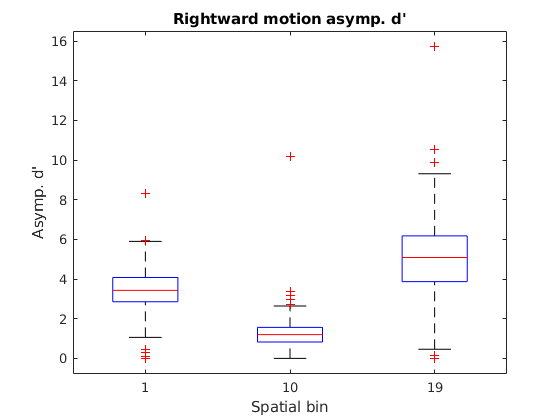

figure;
boxplot(dp_right(:,[1 10 19]));
set(gca, 'XTickLabels', {1, 10, 19});
xlabel 'Spatial bin'
ylabel 'Asymp. d'''
title 'Rightward motion asymp. d'''

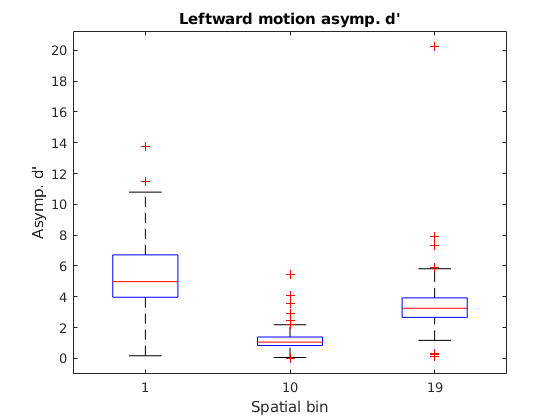

figure;
boxplot(dp_left(:,[1 10 19]));
set(gca, 'XTickLabels', {1, 10, 19});
xlabel 'Spatial bin'
ylabel 'Asymp. d'''
title 'Leftward motion asymp. d'''


dp_right = sqrt(median(asnr(:,d==0))).';
dp_left = sqrt(median(asnr(:,d==1))).';

bin_position = (1.5:19.5).';
dist_from_center = abs((1.5:19.5) - 10.5).';

tab = array2table([bin_position, dist_from_center, dp_right, dp_left],...
    'VariableNames', {'Bin', 'Dist', 'dp_right', 'dp_left'});

fitlm(tab, 'dp_right ~ 1 + Bin + Dist')

ans = Linear regression model:
    dp_right ~ 1 + Bin + Dist

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     0.13156     0.42913    0.30657       0.76312
    Bin            0.031293    0.028342     1.1041       0.28586
    Dist            0.28231    0.056449      5.001    0.00013059


Number of observations: 19, Error degrees of freedom: 16
Root Mean Squared Error: 0.677
R-squared: 0.621,  Adjusted R-Squared: 0.574
F-statistic vs. constant model: 13.1, p-value = 0.000425

fitlm(tab, 'dp_left ~ 1 + Bin + Dist')

ans = Linear regression model:
    dp_left ~ 1 + Bin + Dist

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)      0.82553     0.39083     2.1123      0.050737
    Bin            -0.036706    0.025812    -1.4221       0.17421
    Dist             0.28578     0.05141     5.5588    4.3199e-05


Number of observations: 19, Error degrees of freedom: 16
Root Mean Squared Error: 0.616
R-squared: 0.673,  Adjusted R-Squared: 0.632
F-statistic vs. constant model: 16.5, p-value = 0.000131

## Repeating the asymp SNR ratio to effective number correlation per bin

sm = SessManager;
for ix = 1:sm.num_usable
    [~, ~, ~, ~, ~, ~, out{ix}] =...
    calculate_slopes_bins(ix, signal, noise, noise_shuf, res);
    [~, mouse_names_usable] = sm.usable_sess_id_list;
    asnr_ratio_bins{ix} = out{ix}.asnr_ratio;
    asnr_ratio_bins_conf{ix} = out{ix}.asnr_ratio_conf;
end

org = Org;
org.init;

my_mice = SessManager.highqual_mice;
for m_i = 1:numel(my_mice)
    my_mouse = my_mice{m_i};
    [eff_m{m_i}, eff_s{m_i}] = org.mouse_by_bins('dmu_ipr', {my_mouse, 'restrict'});
    %[asr_m{m_i}, asr_s{m_i}] = org.mouse_by_bins('inv_asymp_ratio', {my_mouse, 'restrict'});
    sess_filt = strcmp(mouse_names_usable, my_mouse) & sm.highqual_filt_from_usable;
    asnr_ratio_mouse = asnr_ratio_bins(sess_filt);
    
    x_ = cell2mat(asnr_ratio_mouse.');
    x_(x_ < 0) = nan;
    x_ = mean(x_, 1, 'omitnan');
    asr_m{m_i}(1:19) = x_(1:19);
    asr_m{m_i}([20 40]) = nan;
    asr_m{m_i}(21:39) = x_(20:38);
end


for b_i = 1:40
    fprintf('Bin index %d\n', b_i);
    if isnan(eff_m{1}(b_i))
        continue;
    end
    bin_eff = cellfun(@(x)x(b_i), eff_m);
    bin_asr = cellfun(@(x)x(b_i), asr_m);
    %Org.corr_check(bin_eff, bin_asr);
    [p,pp,s,sp,k,kp,adjr2] = Org.corr_check_nan(bin_eff, 1./bin_asr);
    fprintf('Mouse-aggregated correlations %s vs. %s: adj. R^2 = %.3f\n', 'effective #', 'inv_asymp_snr', adjr2);
    fprintf('Pearson: %.3f, p = %e, %s\n', p, pp, Utils.pstar(pp));
    fprintf('Spearman: %.3f, p = %e, %s\n', s, sp, Utils.pstar(sp));
    fprintf('Kendall: %.3f, p = %e, %s\n', k, kp, Utils.pstar(kp));
end

Bin index 1


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.478


Pearson: 0.737, p = 2.344373e-02, *


Spearman: 0.267, p = 4.933311e-01, n.s


Kendall: 0.167, p = 6.122024e-01, n.s


Bin index 2


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.567


Pearson: 0.788, p = 1.164822e-02, *


Spearman: 0.450, p = 2.298170e-01, n.s


Kendall: 0.278, p = 3.584877e-01, n.s


Bin index 3


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.495


Pearson: 0.742, p = 1.395853e-02, *


Spearman: 0.612, p = 6.646914e-02, n.s


Kendall: 0.467, p = 7.255015e-02, n.s


Bin index 4


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.490


Pearson: 0.744, p = 2.157000e-02, *


Spearman: 0.533, p = 1.475254e-01, n.s


Kendall: 0.389, p = 1.801808e-01, n.s


Bin index 5


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.210


Pearson: 0.556, p = 1.201554e-01, n.s


Spearman: 0.500, p = 1.776620e-01, n.s


Kendall: 0.389, p = 1.801808e-01, n.s


Bin index 6


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.123


Pearson: -0.045, p = 9.026158e-01, n.s


Spearman: -0.091, p = 8.114170e-01, n.s


Kendall: -0.111, p = 7.274895e-01, n.s


Bin index 7


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.043


Pearson: 0.404, p = 2.814261e-01, n.s


Spearman: 0.383, p = 3.125000e-01, n.s


Kendall: 0.278, p = 3.584877e-01, n.s


Bin index 8


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.088


Pearson: 0.435, p = 2.086706e-01, n.s


Spearman: 0.503, p = 1.433668e-01, n.s


Kendall: 0.422, p = 1.083135e-01, n.s


Bin index 9


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.496


Pearson: 0.743, p = 1.376783e-02, *


Spearman: 0.794, p = 9.844136e-03, **


Kendall: 0.644, p = 9.148479e-03, **


Bin index 10


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.252


Pearson: 0.579, p = 7.972199e-02, n.s


Spearman: 0.321, p = 3.676840e-01, n.s


Kendall: 0.244, p = 3.807198e-01, n.s


Bin index 11


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.347


Pearson: 0.648, p = 4.295455e-02, *


Spearman: 0.612, p = 6.646914e-02, n.s


Kendall: 0.511, p = 4.662257e-02, *


Bin index 12


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.154


Pearson: 0.498, p = 1.429717e-01, n.s


Spearman: 0.382, p = 2.789652e-01, n.s


Kendall: 0.289, p = 2.912483e-01, n.s


Bin index 13


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.497


Pearson: 0.743, p = 1.371098e-02, *


Spearman: 0.806, p = 8.235571e-03, **


Kendall: 0.689, p = 4.686949e-03, **


Bin index 14


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.036


Pearson: 0.306, p = 4.228566e-01, n.s


Spearman: -0.133, p = 7.435406e-01, n.s


Kendall: -0.111, p = 7.614142e-01, n.s


Bin index 15


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.097


Pearson: -0.444, p = 1.986262e-01, n.s


Spearman: -0.164, p = 6.567214e-01, n.s


Kendall: -0.067, p = 8.618006e-01, n.s


Bin index 16


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.111


Pearson: 0.111, p = 7.594998e-01, n.s


Spearman: 0.224, p = 5.366881e-01, n.s


Kendall: 0.111, p = 7.274895e-01, n.s


Bin index 17


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.137


Pearson: -0.073, p = 8.522991e-01, n.s


Spearman: -0.033, p = 9.483907e-01, n.s


Kendall: 0.000, p = 1.000000e+00, n.s


Bin index 18


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.105


Pearson: -0.134, p = 7.118050e-01, n.s


Spearman: 0.091, p = 8.114170e-01, n.s


Kendall: 0.111, p = 7.274895e-01, n.s


Bin index 19


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.088


Pearson: -0.181, p = 6.170834e-01, n.s


Spearman: -0.079, p = 8.380041e-01, n.s


Kendall: -0.067, p = 8.618006e-01, n.s


Bin index 20
Bin index 21


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.365


Pearson: 0.660, p = 3.787493e-02, *


Spearman: 0.418, p = 2.324181e-01, n.s


Kendall: 0.333, p = 2.163735e-01, n.s


Bin index 22


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.117


Pearson: 0.084, p = 8.166637e-01, n.s


Spearman: -0.067, p = 8.647535e-01, n.s


Kendall: -0.111, p = 7.274895e-01, n.s


Bin index 23


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.597


Pearson: 0.809, p = 1.500895e-02, *


Spearman: 0.810, p = 2.177579e-02, *


Kendall: 0.643, p = 3.115079e-02, *


Bin index 24


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.228


Pearson: 0.560, p = 9.202746e-02, n.s


Spearman: 0.612, p = 6.646914e-02, n.s


Kendall: 0.422, p = 1.083135e-01, n.s


Bin index 25


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.543


Pearson: 0.775, p = 1.422803e-02, *


Spearman: 0.833, p = 8.267196e-03, **


Kendall: 0.667, p = 1.266534e-02, *


Bin index 26


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.292


Pearson: 0.609, p = 6.179561e-02, n.s


Spearman: 0.333, p = 3.488462e-01, n.s


Kendall: 0.289, p = 2.912483e-01, n.s


Bin index 27


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.574


Pearson: 0.792, p = 1.094931e-02, *


Spearman: 0.867, p = 4.508377e-03, **


Kendall: 0.722, p = 5.886243e-03, **


Bin index 28


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.323


Pearson: 0.631, p = 5.052491e-02, n.s


Spearman: 0.297, p = 4.069502e-01, n.s


Kendall: 0.244, p = 3.807198e-01, n.s


Bin index 29


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.219


Pearson: 0.553, p = 9.712754e-02, n.s


Spearman: 0.673, p = 3.938141e-02, *


Kendall: 0.467, p = 7.255015e-02, n.s


Bin index 30


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.503


Pearson: 0.747, p = 1.296347e-02, *


Spearman: 0.055, p = 8.916388e-01, n.s


Kendall: 0.022, p = 1.000000e+00, n.s


Bin index 31


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.107


Pearson: 0.454, p = 1.878075e-01, n.s


Spearman: 0.321, p = 3.676840e-01, n.s


Kendall: 0.244, p = 3.807198e-01, n.s


Bin index 32


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.270


Pearson: 0.593, p = 7.101525e-02, n.s


Spearman: 0.491, p = 1.544427e-01, n.s


Kendall: 0.333, p = 2.163735e-01, n.s


Bin index 33


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.417


Pearson: 0.694, p = 2.594343e-02, *


Spearman: 0.612, p = 6.646914e-02, n.s


Kendall: 0.422, p = 1.083135e-01, n.s


Bin index 34


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.469


Pearson: 0.731, p = 2.510884e-02, *


Spearman: 0.867, p = 4.508377e-03, **


Kendall: 0.722, p = 5.886243e-03, **


Bin index 35


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.365


Pearson: 0.660, p = 3.774551e-02, *


Spearman: 0.588, p = 8.021506e-02, n.s


Kendall: 0.467, p = 7.255015e-02, n.s


Bin index 36


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.456


Pearson: 0.719, p = 1.915977e-02, *


Spearman: 0.600, p = 7.311988e-02, n.s


Kendall: 0.467, p = 7.255015e-02, n.s


Bin index 37


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.614


Pearson: 0.814, p = 7.604458e-03, **


Spearman: 0.933, p = 7.495591e-04, ***


Kendall: 0.833, p = 8.542769e-04, ***


Bin index 38


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = -0.111


Pearson: 0.167, p = 6.673338e-01, n.s


Spearman: 0.167, p = 6.777447e-01, n.s


Kendall: 0.111, p = 7.614142e-01, n.s


Bin index 39


Mouse-aggregated correlations effective # vs. inv_asymp_snr: adj. R^2 = 0.040


Pearson: 0.421, p = 2.986703e-01, n.s


Spearman: 0.500, p = 2.161706e-01, n.s


Kendall: 0.429, p = 1.788690e-01, n.s


Bin index 40


my_mice = SessManager.highqual_mice;
for m_i = 1:numel(my_mice)
    my_mouse = my_mice{m_i};
    [PSS_m{m_i}, PSS_s{m_i}] = org.mouse_by_bins('signal_density', {my_mouse, 'restrict'});
    %[asr_m{m_i}, asr_s{m_i}] = org.mouse_by_bins('inv_asymp_ratio', {my_mouse, 'restrict'});
    sess_filt = strcmp(mouse_names_usable, my_mouse) & sm.highqual_filt_from_usable;
    asnr_ratio_mouse = asnr_ratio_bins(sess_filt);
    
    x_ = cell2mat(asnr_ratio_mouse.');
    x_(x_ < 0) = nan;
    x_ = mean(x_, 1, 'omitnan');
    asr_m{m_i}(1:19) = x_(1:19);
    asr_m{m_i}([20 40]) = nan;
    asr_m{m_i}(21:39) = x_(20:38);
end


for b_i = 1:40
    fprintf('Bin index %d\n', b_i);
    if isnan(PSS_m{1}(b_i))
        continue;
    end
    bin_PSS = cellfun(@(x)x(b_i), PSS_m);
    bin_asr = cellfun(@(x)x(b_i), asr_m);
    %Org.corr_check(bin_eff, bin_asr);
    [p,pp,s,sp,k,kp,adjr2] = Org.corr_check_nan(bin_PSS, bin_asr);
    fprintf('Mouse-aggregated correlations %s vs. %s: adj. R^2 = %.3f\n', 'PSS', 'asymp_snr', adjr2);
    fprintf('Pearson: %.3f, p = %e, %s\n', p, pp, Utils.pstar(pp));
    fprintf('Spearman: %.3f, p = %e, %s\n', s, sp, Utils.pstar(sp));
    fprintf('Kendall: %.3f, p = %e, %s\n', k, kp, Utils.pstar(kp));
end

Bin index 1


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.189


Pearson: 0.539, p = 1.345248e-01, n.s


Spearman: 0.350, p = 3.585813e-01, n.s


Kendall: 0.278, p = 3.584877e-01, n.s


Bin index 2


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.077


Pearson: -0.240, p = 5.340200e-01, n.s


Spearman: -0.200, p = 6.134039e-01, n.s


Kendall: -0.111, p = 7.614142e-01, n.s


Bin index 3


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.033


Pearson: -0.375, p = 2.854189e-01, n.s


Spearman: -0.382, p = 2.789652e-01, n.s


Kendall: -0.200, p = 4.843127e-01, n.s


Bin index 4


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.087


Pearson: -0.448, p = 2.260105e-01, n.s


Spearman: -0.267, p = 4.933311e-01, n.s


Kendall: -0.278, p = 3.584877e-01, n.s


Bin index 5


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.130


Pearson: 0.108, p = 7.820006e-01, n.s


Spearman: 0.050, p = 9.116182e-01, n.s


Kendall: 0.056, p = 9.194555e-01, n.s


Bin index 6


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.150


Pearson: 0.495, p = 1.462421e-01, n.s


Spearman: 0.309, p = 3.870550e-01, n.s


Kendall: 0.289, p = 2.912483e-01, n.s


Bin index 7


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.042


Pearson: -0.297, p = 4.378789e-01, n.s


Spearman: -0.383, p = 3.125000e-01, n.s


Kendall: -0.278, p = 3.584877e-01, n.s


Bin index 8


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.076


Pearson: -0.209, p = 5.630064e-01, n.s


Spearman: -0.236, p = 5.138983e-01, n.s


Kendall: -0.156, p = 6.006537e-01, n.s


Bin index 9


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.230


Pearson: -0.562, p = 9.116072e-02, n.s


Spearman: -0.576, p = 8.776804e-02, n.s


Kendall: -0.422, p = 1.083135e-01, n.s


Bin index 10


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.004


Pearson: 0.327, p = 3.558068e-01, n.s


Spearman: 0.042, p = 9.186333e-01, n.s


Kendall: 0.022, p = 1.000000e+00, n.s


Bin index 11


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.173


Pearson: -0.515, p = 1.277790e-01, n.s


Spearman: -0.491, p = 1.544427e-01, n.s


Kendall: -0.289, p = 2.912483e-01, n.s


Bin index 12


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.194


Pearson: -0.533, p = 1.128718e-01, n.s


Spearman: -0.333, p = 3.488462e-01, n.s


Kendall: -0.200, p = 4.843127e-01, n.s


Bin index 13


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.101


Pearson: -0.448, p = 1.939019e-01, n.s


Spearman: -0.370, p = 2.956041e-01, n.s


Kendall: -0.333, p = 2.163735e-01, n.s


Bin index 14


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.256


Pearson: 0.591, p = 9.393548e-02, n.s


Spearman: 0.550, p = 1.327767e-01, n.s


Kendall: 0.444, p = 1.194389e-01, n.s


Bin index 15


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.106


Pearson: -0.130, p = 7.196772e-01, n.s


Spearman: 0.442, p = 2.042006e-01, n.s


Kendall: 0.378, p = 1.557418e-01, n.s


Bin index 16


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.087


Pearson: 0.184, p = 6.114082e-01, n.s


Spearman: -0.055, p = 8.916388e-01, n.s


Kendall: -0.067, p = 8.618006e-01, n.s


Bin index 17


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.114


Pearson: -0.158, p = 6.854621e-01, n.s


Spearman: 0.333, p = 3.853230e-01, n.s


Kendall: 0.278, p = 3.584877e-01, n.s


Bin index 18


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.125


Pearson: -0.019, p = 9.585655e-01, n.s


Spearman: 0.067, p = 8.647535e-01, n.s


Kendall: 0.022, p = 1.000000e+00, n.s


Bin index 19


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.124


Pearson: 0.035, p = 9.229731e-01, n.s


Spearman: 0.042, p = 9.186333e-01, n.s


Kendall: 0.067, p = 8.618006e-01, n.s


Bin index 20
Bin index 21


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.125


Pearson: -0.006, p = 9.874183e-01, n.s


Spearman: -0.333, p = 3.488462e-01, n.s


Kendall: -0.244, p = 3.807198e-01, n.s


Bin index 22


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.021


Pearson: 0.304, p = 3.924290e-01, n.s


Spearman: 0.273, p = 4.482722e-01, n.s


Kendall: 0.244, p = 3.807198e-01, n.s


Bin index 23


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.238


Pearson: -0.589, p = 1.244910e-01, n.s


Spearman: -0.619, p = 1.149802e-01, n.s


Kendall: -0.429, p = 1.788690e-01, n.s


Bin index 24


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.103


Pearson: -0.450, p = 1.915601e-01, n.s


Spearman: -0.491, p = 1.544427e-01, n.s


Kendall: -0.333, p = 2.163735e-01, n.s


Bin index 25


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.420


Pearson: -0.702, p = 3.513264e-02, *


Spearman: -0.500, p = 1.776620e-01, n.s


Kendall: -0.389, p = 1.801808e-01, n.s


Bin index 26


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.067


Pearson: -0.226, p = 5.298799e-01, n.s


Spearman: -0.018, p = 9.728412e-01, n.s


Kendall: -0.022, p = 1.000000e+00, n.s


Bin index 27


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.262


Pearson: -0.595, p = 9.087658e-02, n.s


Spearman: -0.600, p = 9.679784e-02, n.s


Kendall: -0.444, p = 1.194389e-01, n.s


Bin index 28


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.110


Pearson: 0.117, p = 7.468922e-01, n.s


Spearman: 0.006, p = 1.000000e+00, n.s


Kendall: -0.067, p = 8.618006e-01, n.s


Bin index 29


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.040


Pearson: -0.383, p = 2.749899e-01, n.s


Spearman: -0.321, p = 3.676840e-01, n.s


Kendall: -0.200, p = 4.843127e-01, n.s


Bin index 30


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.035


Pearson: 0.377, p = 2.825207e-01, n.s


Spearman: 0.309, p = 3.870550e-01, n.s


Kendall: 0.067, p = 8.618006e-01, n.s


Bin index 31


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.025


Pearson: -0.299, p = 4.018576e-01, n.s


Spearman: 0.261, p = 4.696753e-01, n.s


Kendall: 0.156, p = 6.006537e-01, n.s


Bin index 32


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.033


Pearson: 0.286, p = 4.232079e-01, n.s


Spearman: 0.127, p = 7.328868e-01, n.s


Kendall: 0.156, p = 6.006537e-01, n.s


Bin index 33


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.077


Pearson: -0.424, p = 2.220583e-01, n.s


Spearman: -0.297, p = 4.069502e-01, n.s


Kendall: -0.244, p = 3.807198e-01, n.s


Bin index 34


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.334


Pearson: -0.646, p = 6.010150e-02, n.s


Spearman: -0.667, p = 5.888999e-02, n.s


Kendall: -0.500, p = 7.517637e-02, n.s


Bin index 35


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.064


Pearson: -0.233, p = 5.170461e-01, n.s


Spearman: -0.164, p = 6.567214e-01, n.s


Kendall: -0.111, p = 7.274895e-01, n.s


Bin index 36


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.112


Pearson: -0.107, p = 7.693412e-01, n.s


Spearman: -0.333, p = 3.488462e-01, n.s


Kendall: -0.200, p = 4.843127e-01, n.s


Bin index 37


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = 0.214


Pearson: -0.559, p = 1.175420e-01, n.s


Spearman: -0.300, p = 4.366237e-01, n.s


Kendall: -0.222, p = 4.767086e-01, n.s


Bin index 38


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.139


Pearson: 0.059, p = 8.810966e-01, n.s


Spearman: 0.417, p = 2.695822e-01, n.s


Kendall: 0.333, p = 2.595183e-01, n.s


Bin index 39


Mouse-aggregated correlations PSS vs. asymp_snr: adj. R^2 = -0.131


Pearson: 0.174, p = 6.796946e-01, n.s


Spearman: -0.143, p = 7.520337e-01, n.s


Kendall: -0.071, p = 9.048611e-01, n.s


Bin index 40


function snr_data = fetch_snr_data(ix, signal, noise, noise_shuf, res)

s = signal{ix};
x.s_m = squeeze(mean(s)); x.s_s = squeeze(std(s)./sqrt(size(s,1)));

n = noise{ix};
x.n_m = squeeze(mean(n)); x.n_s = squeeze(std(n)./sqrt(size(n,1)));

ns = noise_shuf{ix};
x.ns_m = squeeze(mean(ns)); x.ns_s = squeeze(std(ns)./sqrt(size(ns,1)));


snr = s ./ n;
x.snr_m = squeeze(mean(snr)); x.snr_s = squeeze(std(snr)./sqrt(size(snr,1)));

snrs = s ./ ns;
x.snrs_m = squeeze(mean(snrs)); x.snrs_s = squeeze(std(snrs)./sqrt(size(snrs,1)));

x.nneu = res(ix).n_sizes;

snr_data = x;
snr_data.sess_idx = ix;
end

function kd = bb2kd(bb)
kd = [ceil(bb/2), mod(bb,2)];
end


function old_style_plot(snr_data, n_bin_bounds)
x = snr_data;
nneu = x.nneu;
s_m = x.s_m;
s_s = x.s_s;
n_m = x.n_m;
n_s = x.n_s;
ns_m = x.ns_m;
ns_s = x.ns_s;
snr_m = x.snr_m;
snr_s = x.snr_s;
snrs_m = x.snrs_m;
snrs_s = x.snrs_s;

figure('Units',"inches", 'Position',[3.5603    0.8276   16.2500   16.3448]);

bin_colors = jet(n_bin_bounds/2);

for b = 1:n_bin_bounds
    kd = bb2kd(b);
    k = kd(1);
    switch kd(2)
        case 0
            d = 'right';
            is_right = 1;
        case 1
            d = 'left';
            is_right = 0;
    end
    
    
    subplot(6,2,1*2 + is_right - 1);
    shadedErrorBar(nneu.', s_m(:,b), s_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Signal'
    ylim([0 max(s_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,2*2 + is_right - 1);
    shadedErrorBar(nneu.', n_m(:,b), n_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Noise'
    ylim([0 max(n_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,3*2 + is_right - 1);
    shadedErrorBar(nneu.', ns_m(:,b), ns_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'Noise (shuffled)'
    ylim([0 max(ns_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,4*2 + is_right - 1);
    shadedErrorBar(nneu.', snr_m(:,b), snr_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'SNR'
    ylim([0 max(snr_m(:))]);
    %set(gca, 'YScale', 'log');
    
    subplot(6,2,5*2 + is_right - 1);
    shadedErrorBar(nneu.', snrs_m(:,b), snrs_s(:,b).*1.96, 'lineprops', {'Color', bin_colors(k,:)});
    xlabel '# neurons'
    ylabel 'SNR (shuffled)'
    ylim([0 max(snrs_m(:))]);
    %set(gca, 'YScale', 'log');
end
subplot(6,2,1); title 'Signal left'
subplot(6,2,2); title 'Signal right'

subplot(6,2,3); title 'Noise left'
subplot(6,2,4); title 'Noise right'

subplot(6,2,5); title 'Noise (shuf) left'
subplot(6,2,6); title 'Noise (shuf) right'

subplot(6,2,7); title 'SNR left'
subplot(6,2,8); title 'SNR right'

subplot(6,2,9); title 'SNR (shuf) left'
subplot(6,2,10); title 'SNR (shuf) right'
subplot(6,2,[11 12]);
imagesc(1:19);
axis image
colormap jet
set(gca, 'YTickLabels', []);
xticks(1:19);
set(get(gca, 'XAxis'), 'TickLength', [0 0]);
xlabel 'Spatial bins'
sgtitle(sprintf('Session number %d', x.sess_idx));
end

function osp(ix, signal, noise, noise_shuf, res)
old_style_plot(fetch_snr_data(ix, signal, noise, noise_shuf, res), 38);
end

function [r, c] = c_agg_bins(q)
sd_bins = (1:38).';
kd = bb2kd(sd_bins);
k = kd(:,1);
e_bins = ismember(k, [1 2 18 19]);
fs_bins = ismember(k, [3 4 16 17]);
ms_bins = ismember(k, [5 6 14 15]);
ns_bins = ismember(k, [7 8 12 13]);
c_bins = ismember(k, [9 10 11]);

r(:,1) = mean(q(:,e_bins),2);
r(:,2) = mean(q(:,fs_bins),2);
r(:,3) = mean(q(:,ms_bins),2);
r(:,4) = mean(q(:,ns_bins),2);
r(:,5) = mean(q(:,c_bins),2);

c = {'e', 'fs', 'ms', 'ns', 'c'};
end

function [snr_data, categories] = agg_snr_data(snr_data)
vars = {
's_m'
's_s'
'n_m'
'n_s'
'ns_m'
'ns_s'
'snr_m'
'snr_s'
'snrs_m'
'snrs_s'
};

for i = 1:numel(vars)
  my_var = vars{i};
  [snr_data.(my_var), categories] = c_agg_bins(snr_data.(my_var));
end

end

function c_legend(cmap, pos, tt)
%axes('Position', [0.2 0.7 0.6 0.6]);
axes('Position', pos);
imagesc([1 1 2 2 3 3 4 4 5 5 5 4 4 3 3 2 2 1 1]);
colormap(gca, cmap)
axis image
axis off
title(tt);
end

function new_plot_sess(isscaled, ix, signal, noise, noise_shuf, res)
snr_data = fetch_snr_data(ix, signal, noise, noise_shuf, res);
[snr_data, ~] = agg_snr_data(snr_data);
x = snr_data;

c_colors = flipud(winter(5));
c_colors_shuf = flipud(spring(5));

nexttile
for i = 1:5
    hold on;
    if isscaled, sc = x.s_m(end,i); else, sc = 1; end
    shadedErrorBar(x.nneu.', x.s_m(:,i)./sc, x.s_s(:,i)./sc, 'lineprops', {'Color', c_colors(i,:)});
end
xlabel 'Num. neurons'
if isscaled
    ylabel(sprintf('Signal\n(scaled)'));
else
    ylabel(sprintf('Signal\n(events^2)'));
end

nexttile
for i = 1:5
    hold on;
    if isscaled, sc = x.n_m(end,i); else, sc = 1; end
    shadedErrorBar(x.nneu.', x.n_m(:,i)./sc, x.n_s(:,i)./sc, 'lineprops', {'Color', c_colors(i,:)});
    shadedErrorBar(x.nneu.', x.ns_m(:,i)./sc, x.ns_s(:,i)./sc, 'lineprops', {'Color', c_colors_shuf(i,:)});
end
xlabel 'Num. neurons'
if isscaled
    ylabel(sprintf('Noise\n(scaled)'));
else
    ylabel(sprintf('Noise\n(events^2)'));
end

nexttile
for i = 1:5
    hold on;
    if isscaled, sc = x.snr_m(end,i); else, sc = 1; end
    shadedErrorBar(x.nneu.', x.snr_m(:,i)./sc, x.snr_s(:,i)./sc, 'lineprops', {'Color', c_colors(i,:)});
    shadedErrorBar(x.nneu.', x.snrs_m(:,i)./sc, x.snrs_s(:,i)./sc, 'lineprops', {'Color', c_colors_shuf(i,:)});
end
xlabel 'Num. neurons'
if isscaled
    ylabel(sprintf('Signal/Noise\n(scaled)'));
else
    ylabel 'Signal/Noise';
end
end

function [asnr, asnr_conf, asnr_shuf, asnr_shuf_conf, asnr_ratio, asnr_ratio_conf] =...
    calculate_asymp_snr(ix, signal, noise, noise_shuf, res)
snr_data = fetch_snr_data(ix, signal, noise, noise_shuf, res);
[snr_data, ~] = agg_snr_data(snr_data);
x = snr_data;

n_cutoff = 100;
for i = 1:5
    [s_slope, s_slope_conf] = Utils.fitaline(x.nneu, x.s_m(:,i).', n_cutoff);
    [n_slope, n_slope_conf] = Utils.fitaline(x.nneu, x.n_m(:,i).', n_cutoff);
    [ns_slope, ns_slope_conf] = Utils.fitaline(x.nneu, x.ns_m(:,i).', n_cutoff);
    
    [asnr(i), asnr_conf(i)] = uncertain_divide(s_slope, s_slope_conf,...
        n_slope, n_slope_conf);
    [asnr_shuf(i), asnr_shuf_conf(i)] = uncertain_divide(s_slope, s_slope_conf,...
        ns_slope, ns_slope_conf);
    [asnr_ratio(i), asnr_ratio_conf(i)] = uncertain_divide(asnr(i), asnr_conf(i),...
        asnr_shuf(i), asnr_shuf_conf(i));
end
end

function [s_slope, s_slope_conf, n_slope, n_slope_conf, asnr, asnr_conf, out] =...
    calculate_slopes_bins(ix, signal, noise, noise_shuf, res)
snr_data = fetch_snr_data(ix, signal, noise, noise_shuf, res);
%[snr_data, ~] = agg_snr_data(snr_data);
x = snr_data;

n_cutoff = 100;
for i = 1:size(x.s_m,2)
    [s_slope(i), s_slope_conf(i)] = Utils.fitaline(x.nneu, x.s_m(:,i).', n_cutoff);
    [n_slope(i), n_slope_conf(i)] = Utils.fitaline(x.nneu, x.n_m(:,i).', n_cutoff);
    [ns_slope(i), ns_slope_conf(i)] = Utils.fitaline(x.nneu, x.ns_m(:,i).', n_cutoff);
    
    [asnr(i), asnr_conf(i)] = uncertain_divide(s_slope(i), s_slope_conf(i),...
        n_slope(i), n_slope_conf(i));
    [asnr_shuf(i), asnr_shuf_conf(i)] = uncertain_divide(s_slope(i), s_slope_conf(i),...
        ns_slope(i), ns_slope_conf(i));
    [asnr_ratio(i), asnr_ratio_conf(i)] = uncertain_divide(asnr(i), asnr_conf(i),...
        asnr_shuf(i), asnr_shuf_conf(i));
end
out.s_slope = s_slope;
out.s_slope_conf = s_slope_conf;

out.n_slope = n_slope;
out.n_slope_conf = n_slope_conf;

out.asnr = asnr;
out.asnr_conf = asnr_conf;

out.asnr_shuf = asnr_shuf;
out.asnr_shuf_conf = asnr_shuf_conf;

out.asnr_ratio = asnr_ratio;
out.asnr_ratio_conf = asnr_ratio_conf;
end